clc; clear; close all;

C = 27;
d = 4;
n_r = 1;

%% Loading FC Data
if(exist(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']) == 0 | ...
   exist(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']) == 0)
    disp('FC data not found. Generating FC operators... \n');
    generate_bdry_continuations(d, C, C, 12, 20, 4, ...
        256, n_r);
end

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']);

A = double(A);
Q = double(Q);

n_bound = 80;
R_h = 0.2/(n_bound)

R_h = 0.0025


f = @(x, y) f_func(x, y);
C1_patch = construct_C1_patch(f, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_bound);
C1_patch_fine = construct_C1_patch(f, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_bound*2);

[C1_fcont_patch_xi, C1_fcont_patch_eta] = C1_patch.FC(C, n_r, d, A, Q, f, d+3)

Not enough input arguments.

Error in C1_patch_obj/FC (line 45)
                [B_c_unrefined_f_XY, B_c_refined_f_XY] = obj.refine_B_c(C, n_r, f, M);

save('C1_fcont_patch_xi_refined.mat', 'C1_fcont_patch_xi')

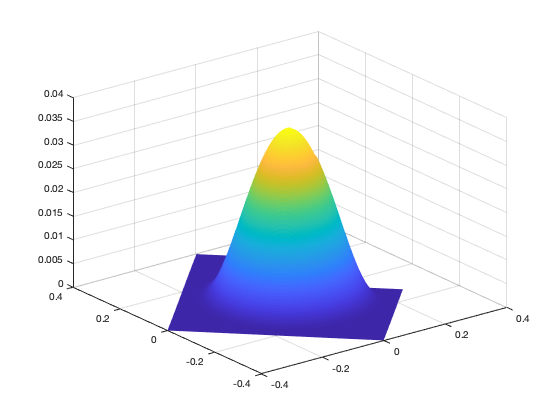

figure;
[X, Y] = C1_fcont_patch_eta.xy_mesh;
s = surf(X, Y, C1_fcont_patch_eta.f_XY);
s.EdgeColor = 'none';
hold on;
[X_B, Y_B] = C1_patch.B.xy_mesh;
s = surf(X_B, Y_B, C1_patch.B.f_XY);
s.EdgeColor = 'none';

[X_Bc, Y_Bc] = C1_patch.B_c.xy_mesh;
s = surf(X_Bc, Y_Bc, C1_patch.B_c.f_XY);
s.EdgeColor = 'none';

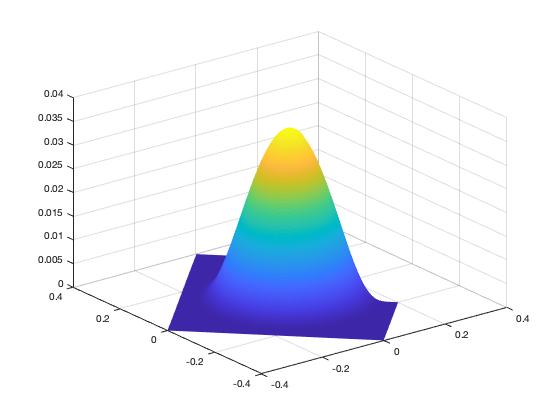

% 
% [X, Y] = C1_fcont_patch_xi.xy_mesh;
% s = surf(X, Y, C1_fcont_patch_xi.f_XY);
% s.EdgeColor = 'none';

figure;
[X, Y] = C1_fcont_patch_xi.xy_mesh;
s = surf(X, Y, C1_fcont_patch_xi.f_XY);
s.EdgeColor = 'none';
hold on;
[X_B, Y_B] = C1_patch.B.xy_mesh;
s = surf(X_B, Y_B, C1_patch.B.f_XY);
s.EdgeColor = 'none';

[X_Bc, Y_Bc] = C1_patch.B_c.xy_mesh;
s = surf(X_Bc, Y_Bc, C1_patch.B_c.f_XY);
s.EdgeColor = 'none';

% R_x_bounds = [C1_patch.B.x_min-0.01, C1_fcont_patch_xi.x_max+0.01]
% R_y_bounds = [C1_patch.B_c.y_min-0.01, C1_patch.B.y_max+0.01]
R_x_bounds = [-0.45, 0.55]

R_x_bounds =     -4.500000000000000e-01     5.500000000000000e-01


R_y_bounds = [-0.45, 0.45]

R_y_bounds =     -4.500000000000000e-01     4.500000000000000e-01


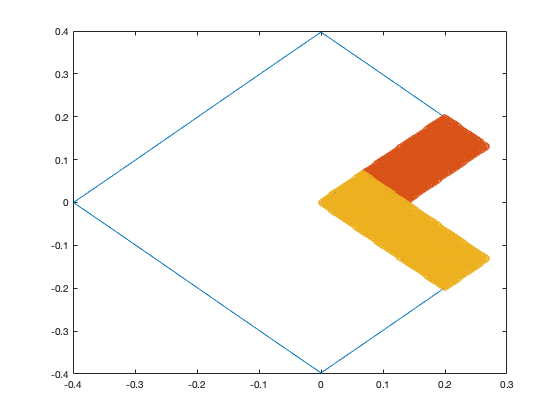


[boundary_X, boundary_Y] = C1_patch.boundary_mesh_xy;

figure;
plot(boundary_X, boundary_Y)
hold on;
[X, Y] = C1_fcont_patch_xi.xy_mesh;
scatter(X(:), Y(:))
[X, Y] = C1_fcont_patch_eta.xy_mesh;
scatter(X(:), Y(:))



R = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);
% hold on;
% scatter(R.R_X(:), R.R_Y(:));
R.interpolate_patch(C1_fcont_patch_xi, d+3, false, f);

start first pass
construct nan map



R.interpolate_patch(C1_fcont_patch_eta, d+3, false, f);

start first pass
construct nan map


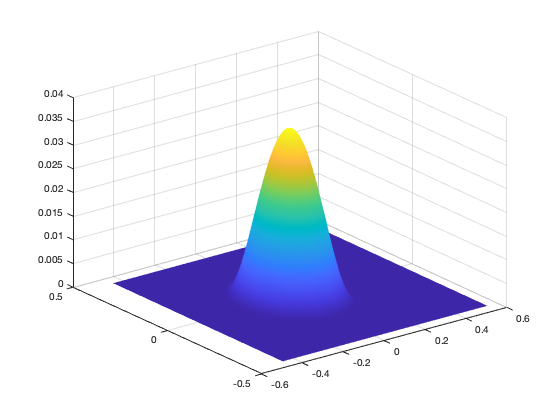

R.fill_interior(f);

figure;
s = surf(R.R_X, R.R_Y, R.f_R);
s.EdgeColor = 'none';

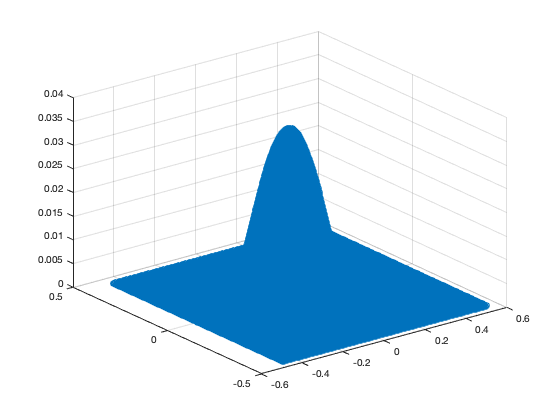


figure;
scatter3(R.R_X(:), R.R_Y(:), R.f_R(:))

R.compute_fc_coeffs()
[X_err, Y_err, f_err, err_interior_idx] = R.ifft_interpolation(R.h * 0.5);

max(abs((f(X_err(err_interior_idx), Y_err(err_interior_idx)) - f_err(err_interior_idx)))) %l_infinity error

ans =      2.669425810605808e-08


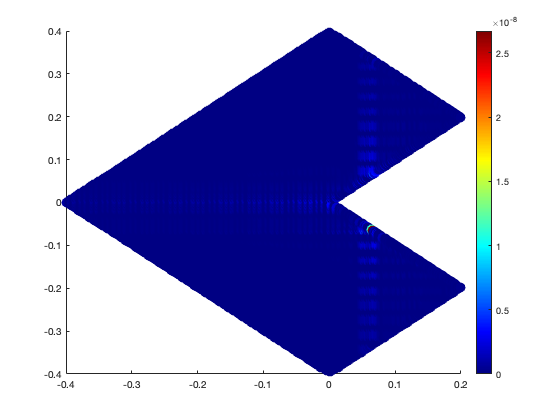


err = abs((f(X_err(err_interior_idx), Y_err(err_interior_idx)) - f_err(err_interior_idx)));

figure;
scatter(X_err(err_interior_idx), Y_err(err_interior_idx), 100, err, 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

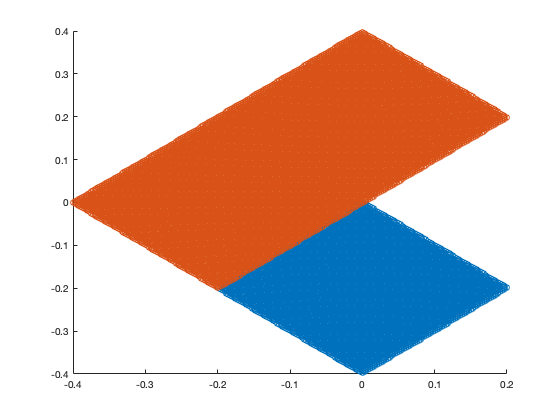


figure;
[X, Y] = C1_patch.B_c.xy_mesh;
scatter(X(:), Y(:))
hold on;
[X, Y] = C1_patch.B.xy_mesh;
scatter(X(:), Y(:))

% xi_mesh = C1_patch.B.eta_mesh;
% eta_mesh = xi_mesh;
% R_mesh = zeros(length(eta_mesh), length(xi_mesh));
% 
% R_mesh(1:n_bound+1, n_bound+1-C:n_bound+1) = C1_fcont_patch_xi.f_XY(:, 1:n_r:end);
% R_mesh(n_bound+1-C:n_bound+1, 1:n_bound+1) = R_mesh(n_bound+1-C:n_bound+1, 1:n_bound+1) + C1_fcont_patch_eta.f_XY(1:n_r:end, :);
% R_mesh(n_bound+2:end, 1:n_bound+1) = C1_patch.B_c.f_XY(2:end, :);
% R_mesh(:, n_bound+2:end) = C1_patch.B.f_XY(:, 2:end);
% 
% [boundary_XI, boundary_ETA] = C1_patch.boundary_mesh;
% R_xi_eta = R_cartesian_mesh_obj(0, 1, 0, 1, C1_patch.h, boundary_XI, boundary_ETA);
% R_xi_eta.f_R = R_mesh;
% 
% R_xi_eta.compute_fc_coeffs;
% 
% figure;
% surf(R_xi_eta.R_X, R_xi_eta.R_Y, R_xi_eta.f_R)
% xlabel('xi')
% ylabel('eta')
% 
% R_xi_eta_finer = R_cartesian_mesh_obj(0, 1, 0, 1, C1_patch.h/2, boundary_XI, boundary_ETA);
% R_xi_eta_finer.f_R(2*n_bound+1:end, 1:2*n_bound+1) = C1_patch_fine.B_c.f_XY;
% R_xi_eta_finer.f_R(:, 2*n_bound+1:end) = C1_patch_fine.B.f_XY;
% 
% figure;
% scatter3(R_xi_eta_finer.R_X(R_xi_eta_finer.interior_idxs), R_xi_eta_finer.R_Y(R_xi_eta_finer.interior_idxs), R_xi_eta_finer.f_R(R_xi_eta_finer.interior_idxs))
% 
% [X_err, Y_err, f_err, err_interior_idx] = R_xi_eta.ifft_interpolation(R_xi_eta.h * 0.5);
% max(abs(f_err(err_interior_idx) - R_xi_eta_finer.f_R(R_xi_eta_finer.interior_idxs)))

% C1_fcont_patch_FFT = construct_Q_patch(R_xi_eta.f_R, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_bound);
% C1_fcont_patch_FFT.compute_xi_eta_fc_coeffs;
% 
% R_FFT = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);
% R_FFT.interpolate_patch(C1_fcont_patch_FFT, 0, true, f);
% R_FFT.fill_interior(f);
% 
% figure;
% s = surf(R_FFT.R_X, R_FFT.R_Y, R_FFT.f_R);
% s.EdgeColor = 'none';
% 
% save('R_FFT_FINE', 'R_FFT');

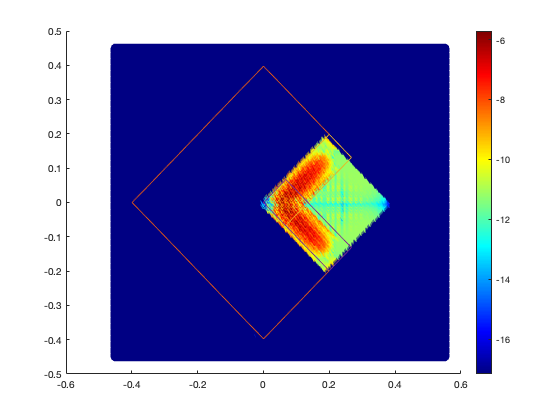

load('R_FFT.mat')
err = abs(R_FFT.f_R - R.f_R);

figure;
scatter(R.R_X(:), R.R_Y(:), 100, log10(err(:)), 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);
hold on;
plot(boundary_X, boundary_Y)

[boundary_X_xi, boundary_Y_xi] = C1_fcont_patch_xi.boundary_mesh_xy;
[boundary_X_eta, boundary_Y_eta] = C1_fcont_patch_eta.boundary_mesh_xy;

plot(boundary_X_xi, boundary_Y_xi);
plot(boundary_X_eta, boundary_Y_eta);

% x = 0.0375; y = -0.035;
% x_j = (x - R_FFT.x_start)/R_FFT.h + 1;
% y_j = (y - R_FFT.y_start)/R_FFT.h + 1;
% f_FFT = R_FFT.f_R(y_j, x_j);
% [xi, eta] = C1_fcont_patch_xi.inverse_M_p(x, y, nan)
% 
% f_xi = C1_fcont_patch_xi.locally_compute(xi, eta, d+3, false);
% f_eta = C1_fcont_patch_eta.locally_compute(xi, eta, d+3, false);
% 
% abs(f_FFT - f_xi - f_eta)

clc; clear; close all;

load('C1_fcont_patch_xi_unrefined.mat')
C1_fcont_patch_xi_unrefined = C1_fcont_patch_xi;
load('C1_fcont_patch_xi_refined.mat')
C1_fcont_patch_xi_refined = C1_fcont_patch_xi;

% x = 0.0375; y = -0.035;
% x_j = (x - R_FFT.x_start)/R_FFT.h + 1;
% y_j = (y - R_FFT.y_start)/R_FFT.h + 1;
% f_FFT = R_FFT.f_R(y_j, x_j);
% [xi, eta] = C1_fcont_patch_xi.inverse_M_p(x, y, nan)

% xi = 4.093625910129755e-01;
% eta = 4.968824448732789e-01;

xi = 3.655919751916676e-01;
eta = 4.093868778008299e-01;

f_unrefined = C1_fcont_patch_xi_unrefined.locally_compute(xi, eta, 7, false)

f_unrefined =      2.632219941104848e-07


f_refined = C1_fcont_patch_xi_refined.locally_compute(xi, eta, 7, false)

f_refined =      2.632219941104848e-07



abs(f_unrefined-f_refined)

ans =      0



[~, h] = C1_fcont_patch_xi_unrefined.h_mesh;

eta_j = floor((eta-C1_fcont_patch_xi_refined.eta_start)/h)

eta_j =     65


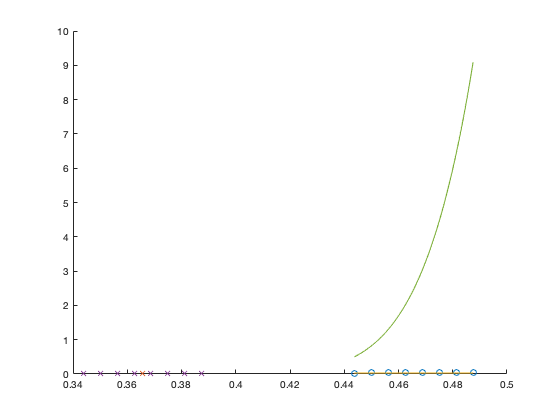

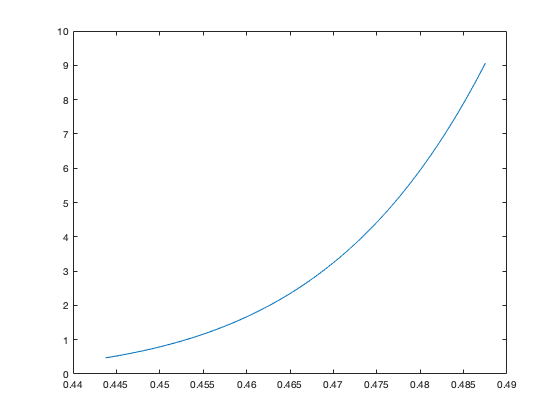


xi_exact_refined = zeros(8, 1);
xi_exact_unrefined = zeros(8, 1);
for i = 63%:70
    figure;
    hold on;
    
    xi_interpol_mesh = C1_fcont_patch_xi_refined.xi_mesh;
    xi_interpol_mesh = xi_interpol_mesh(19:26);
    interpol_f = C1_fcont_patch_xi_refined.f_XY(i, 19:26)';
    scatter(xi_interpol_mesh, interpol_f);
    scatter(xi, 0, 'x')
    mu = [mean(xi_interpol_mesh), std(xi_interpol_mesh)];
    xi_exact_refined(i-62) = barylag([(xi_interpol_mesh-mu(1))/mu(2), interpol_f], (xi-mu(1))/mu(2));
    
    [p, S, mu] = polyfit(xi_interpol_mesh, interpol_f, 7);
    x_fit = linspace(min(xi_interpol_mesh), max(xi_interpol_mesh), 100);
    y_fit_refined = polyval(p, (x_fit-mu(1))/mu(2));
    plot(x_fit, y_fit_refined)
%     xi_exact_refined(i-73) = polyval(p, (xi-mu(1))/mu(2));
    
    xi_interpol_mesh = C1_fcont_patch_xi_unrefined.xi_mesh;
    xi_interpol_mesh = xi_interpol_mesh(3:10);
    interpol_f = C1_fcont_patch_xi_unrefined.f_XY(i, 3:10)';
    
    plot(xi_interpol_mesh, interpol_f, 'x');
    
    mu = [mean(xi_interpol_mesh), std(xi_interpol_mesh)];
    xi_exact_unrefined(i-62) = barylag([(xi_interpol_mesh-mu(1))/mu(2), interpol_f], (xi-mu(1))/mu(2));
    
    [p, S, mu] = polyfit(xi_interpol_mesh, interpol_f, 7);
%     x_fit = linspace(min(xi_interpol_mesh), max(xi_interpol_mesh), 100);
    y_fit_unrefined = polyval(p, (x_fit-mu(1))/mu(2));
    plot(x_fit, y_fit_unrefined)
%     xi_exact_unrefined(i-73) = polyval(p, (xi-mu(1))/mu(2));
    
    figure;
    plot(x_fit, abs(y_fit_unrefined - y_fit_refined))
    
end

xi_exact_refined

xi_exact_refined =     -2.825189817064666e+00
                         0
                         0
                         0
                         0
                         0
                         0
                         0


xi_exact_unrefined

xi_exact_unrefined =      2.477758114666560e-07
                         0
                         0
                         0
                         0
                         0
                         0
                         0


xi_exact_refined - xi_exact_unrefined

ans =     -2.825190064840478e+00
                         0
                         0
                         0
                         0
                         0
                         0
                         0


xi = 4.093625910129755e-01;
eta = 4.968824448732789e-01;

f_unrefined = C1_fcont_patch_xi_unrefined.locally_compute(xi, eta, 7, false)

f_unrefined =      1.072748631777377e-02


f_refined = C1_fcont_patch_xi_refined.locally_compute(xi, eta, 7, false)

f_refined =      1.072748631777377e-02



abs(f_unrefined-f_refined)

ans =      0



[~, h] = C1_fcont_patch_xi_unrefined.h_mesh;

eta_j = floor((eta-C1_fcont_patch_xi_refined.eta_start)/h)

eta_j =     79


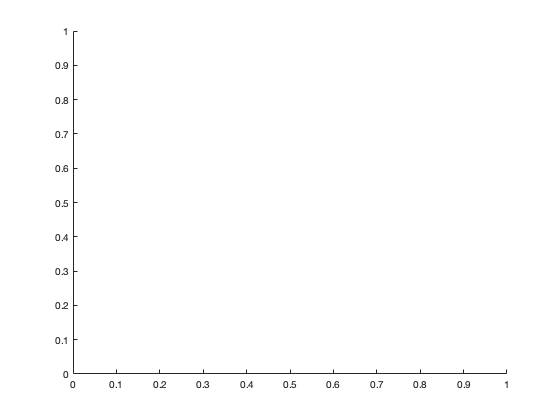

xi_interpol_mesh =      3.312500000000000e-01
     3.375000000000000e-01
     3.437500000000000e-01
     3.500000000000000e-01
     3.562500000000000e-01
     3.625000000000000e-01
     3.687500000000000e-01
     3.750000000000000e-01
     3.812500000000000e-01
     3.875000000000000e-01


Index exceeds the number of array elements (28).


xi_exact_refined = zeros(8, 1);
xi_exact_unrefined = zeros(8, 1);
for i = 74%:81
    figure;
    hold on;
    xi_interpol_mesh = C1_fcont_patch_xi_refined.xi_mesh
    xi_interpol_mesh = xi_interpol_mesh(47:54);
    interpol_f = C1_fcont_patch_xi_refined.f_XY(i, 47:54)';
    scatter(xi_interpol_mesh, interpol_f);
    scatter(xi, 0, 'x')
    mu = [mean(xi_interpol_mesh), std(xi_interpol_mesh)];
    xi_exact_refined(i-73) = barylag([(xi_interpol_mesh-mu(1))/mu(2), interpol_f], (xi-mu(1))/mu(2));
    
    [p, ~, mu] = polyfit(xi_interpol_mesh, interpol_f, 7);
    x_fit = linspace(min(xi_interpol_mesh), max(xi_interpol_mesh), 10000);
    y_fit_refined = polyval(p, (x_fit-mu(1))/mu(2));
%     plot(x_fit, y_fit_refined)

    y_exact_refined = polyval(p, (0.4125-mu(1))/mu(2));
    
    xi_interpol_mesh = C1_fcont_patch_xi_unrefined.xi_mesh;
    xi_interpol_mesh = xi_interpol_mesh(10:17);
    interpol_f = C1_fcont_patch_xi_unrefined.f_XY(i, 10:17)';
    plot(xi_interpol_mesh, interpol_f, 'x');
    
    mu = [mean(xi_interpol_mesh), std(xi_interpol_mesh)];
    xi_exact_unrefined(i-73) = barylag([(xi_interpol_mesh-mu(1))/mu(2), interpol_f], (xi-mu(1))/mu(2));
    
    [p, ~, mu] = polyfit(xi_interpol_mesh, interpol_f, 7);
%     x_fit = linspace(min(xi_interpol_mesh), max(xi_interpol_mesh), 10000);
    y_fit_unrefined = polyval(p, (x_fit-mu(1))/mu(2));
%     plot(x_fit, y_fit_unrefined)
    y_exact_unrefined = polyval(p, (0.4125-mu(1))/mu(2));
    figure; 
    plot(x_fit, abs(y_fit_refined-y_fit_unrefined))
    
    y_exact_unrefined - y_exact_refined
end

xi_exact_refined
xi_exact_unrefined
xi_exact_refined - xi_exact_unrefined

% pnt_lst = [0.0375, -0.035; 0.04, -0.0325; 0.0425, -0.03; 0.045, -0.0275; 0.0475, -0.025; 0.05, -0.0225; 0.0525, -0.02; 0.055, -0.0175; 0.0325, -0.03; 0.03, -0.0275; 0.025, -0.0225; 0.05, -0.0475; 0.02, -0.0175]';
% good_lst = [0.0375, -0.0325; 0.04, -0.03; 0.0425, -0.0275; 0.045, -0.025; 0.0475, -0.0225; 0.05, -0.02; 0.08, 0.0075; 0.089, -0.04; 0.0325, -0.0275; 0.03, -0.025; 0.0175, -0.0125; 0.015, -0.0125]';
% figure;
% [XI, ETA] = C1_fcont_patch_xi_refined.xi_eta_mesh;
% 
% scatter(XI(:), ETA(:));
% hold on;
% 
% [XI_coarse, ETA_coarse] = C1_fcont_patch_xi_unrefined.xi_eta_mesh;
% scatter(XI_coarse(:), ETA_coarse(:), 'x');
% 
% bad_xi_eta = zeros(2, size(pnt_lst, 2));
% for i = 1:size(pnt_lst, 2)
%     pnt = pnt_lst(:, i);
%     
%     [xi, eta] = C1_fcont_patch_xi_refined.inverse_M_p(pnt(1), pnt(2), nan);
%     bad_xi_eta(:, i) = [xi; eta];
% end
% 
% good_xi_eta = zeros(2, size(good_lst, 2));
% 
% for i = 1:size(good_lst, 2)
%     pnt = good_lst(:, i);
%     
%     [xi, eta] = C1_fcont_patch_xi_refined.inverse_M_p(pnt(1), pnt(2), nan);
%     good_xi_eta(:, i) = [xi; eta];
% end
% 
% scatter(bad_xi_eta(1, :), bad_xi_eta(2, :))
% scatter(good_xi_eta(1, :), good_xi_eta(2, :))

function C1_patch = construct_C1_patch(f, theta_A, theta_B, theta_C, theta_D, theta_E, n_bound)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    l_A = @(xi) (theta_D - theta_A)*xi + theta_A;
    l_B = @(eta) (theta_E - theta_B)*eta + theta_B;
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    
    theta_mesh = linspace(theta_D, theta_E, 100)';
    boundary_XY = l_theta(theta_mesh);
    
    J = @(xi, eta) [(theta_D-theta_A)*cos(1/2*((theta_D-theta_A)*xi+theta_A)), (theta_E-theta_B)*cos(1/2*((theta_E-theta_B)*eta+theta_B)); -(theta_D-theta_A)*cos((theta_D-theta_A)*xi+theta_A), -(theta_E-theta_B)*cos((theta_E-theta_B)*eta + theta_B)];
    C1_patch = C1_patch_obj(M_p, @(v) J(v(1), v(2)), n_bound, nan, nan, nan);
    
    [X_B, Y_B] = C1_patch.B.xy_mesh;
    C1_patch.B.f_XY = f(X_B, Y_B);
    
    [X_Bc, Y_Bc] = C1_patch.B_c.xy_mesh;
    C1_patch.B_c.f_XY = f(X_Bc, Y_Bc);
end

function Q_patch = construct_Q_patch(f_XY, theta_A, theta_B, theta_C, theta_D, theta_E, n_bound)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    l_A = @(xi) (theta_D - theta_A)*xi + theta_A;
    l_B = @(eta) (theta_E - theta_B)*eta + theta_B;
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(xi, eta) [(theta_D-theta_A)*cos(1/2*((theta_D-theta_A)*xi+theta_A)), (theta_E-theta_B)*cos(1/2*((theta_E-theta_B)*eta+theta_B)); -(theta_D-theta_A)*cos((theta_D-theta_A)*xi+theta_A), -(theta_E-theta_B)*cos((theta_E-theta_B)*eta + theta_B)];
    Q_patch = Q_patch_obj(M_p, @(v) J(v(1), v(2)), n_bound*2, n_bound*2, 0, 1, 0, 1, f_XY, nan);
end

function f_y = f_func(x, y)
    r0 = 0.3;
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < r0) = exp(1./(1/r0*r(r < r0).^2-r0));
end